# Chapter 1

Singular Data Decomposition (SVD):

The SVD is a unique matrix decomposition that exists for every complex valued

matrix $X\in C^{n\times m}$.  where$\;U\in C^{n\times n}$ and $V\in C^{m\times m}$ are unitary matrices with orthonormal columns, and $\sum \in {R\;}^{n\times m}$ is a matrix with real, non-negative entries on the diagonal and zeros off the diagonal.


$$X=U\Sigma V^*$$


Generally, we are interested in analyzing a large data set $X\in C^{n\times m}$

X = randn(5,3); % Create a 5x3 random data matrix
[U,S,V] = svd(X); % Singular Value Decomposition

Compression:

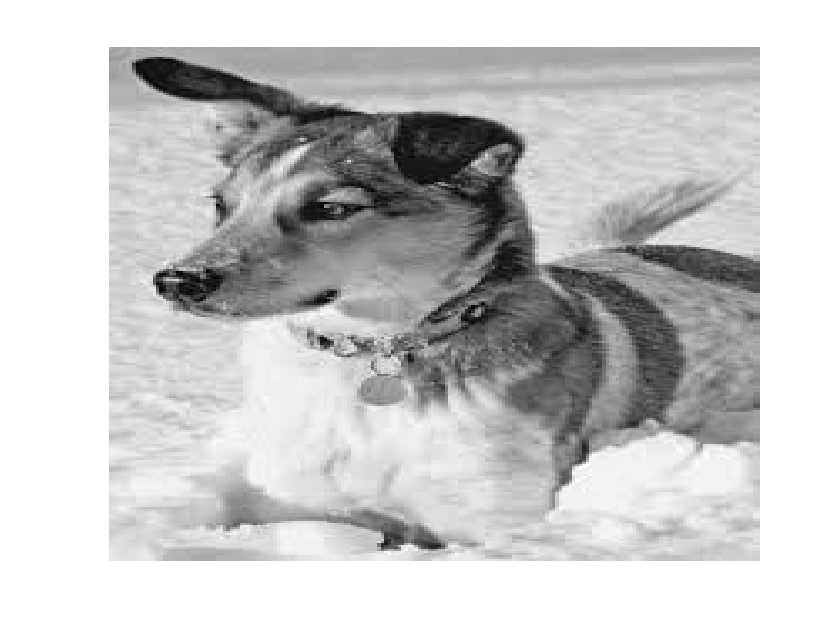

% First, we load the image:
A=imread('Dog.jpg');
X=double(rgb2gray(A)); % Convert RBG->gray, 256 bit->double.
nx = size(X,1); ny = size(X,2);
imagesc(X), axis off, colormap gray

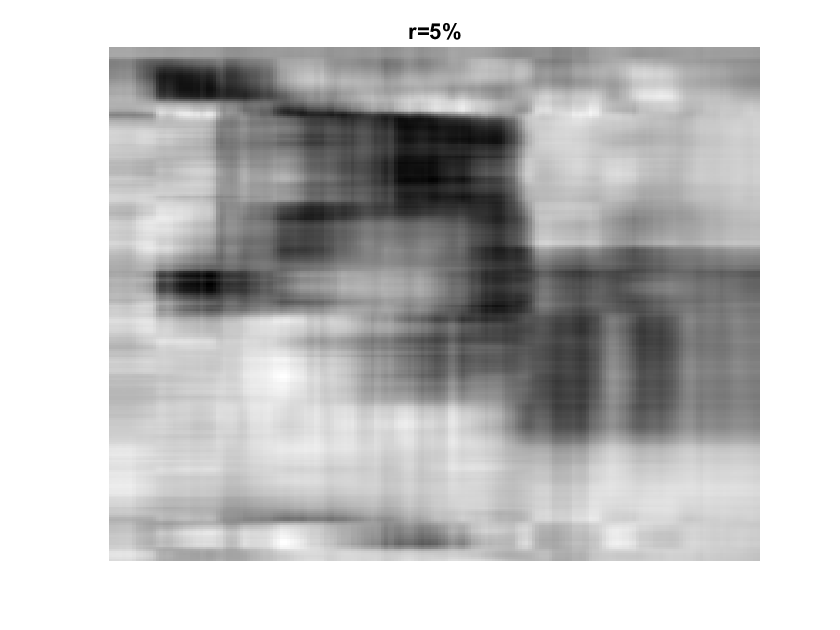

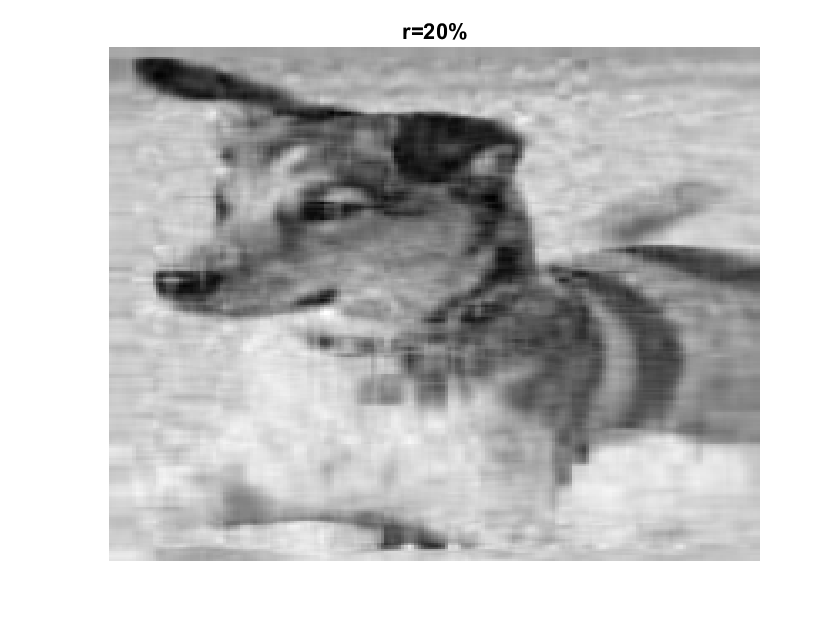

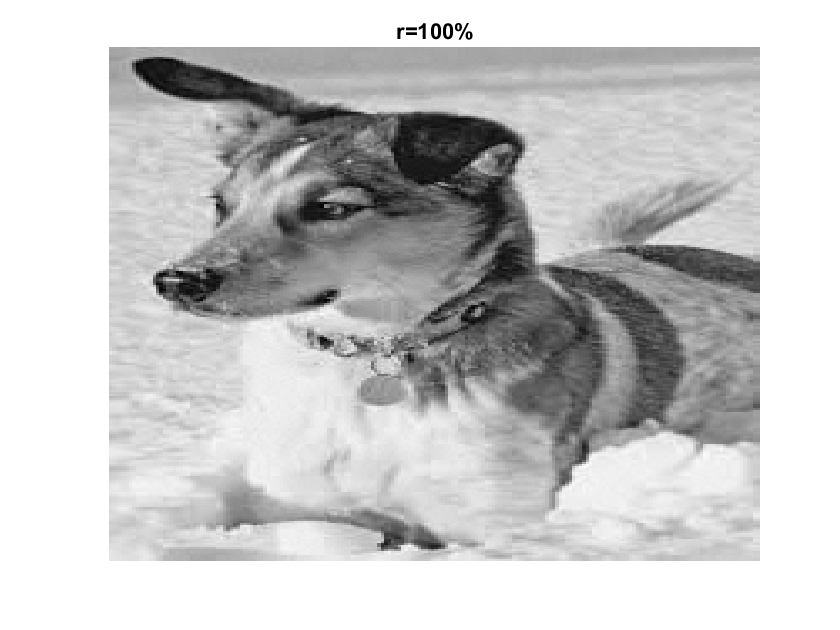


% and take the SVD:
[U,S,V] = svd(X);

% Next, we compute the approximate matrix using the truncated SVD for various
% ranks (r = 5; 20; and 100):

for r=[5 20 100] % Truncation value
Xapprox = U(:,1:r)*S(1:r,1:r)*V(:,1:r)'; % Approx. image
figure, imagesc(Xapprox),colormap gray, axis off
title(['r=',num2str(r),'%']);
end

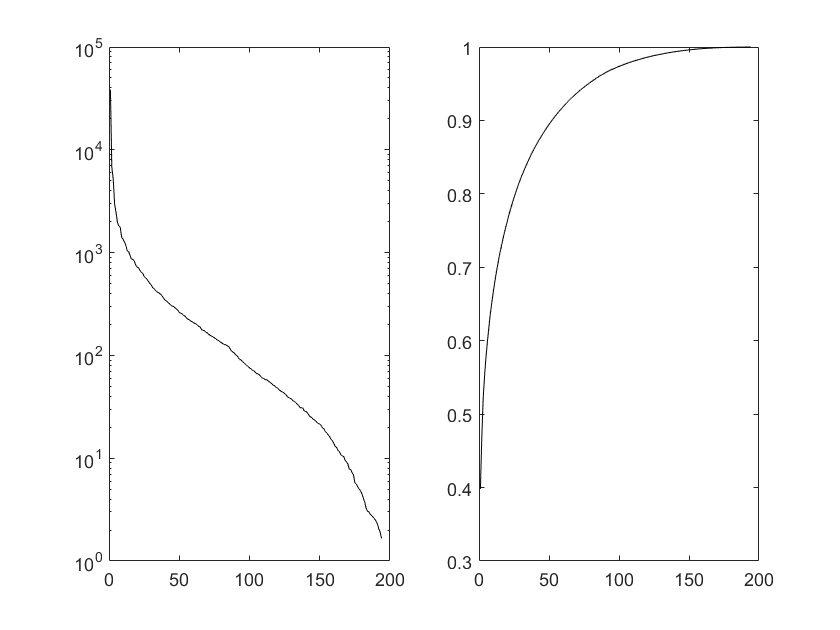


% Finally, we plot the singular values and cumulative energy
subplot(1,2,1), semilogy(diag(S),'k')
subplot(1,2,2), plot(cumsum(diag(S))/sum(diag(S)),'k')